## Space Vehicle Design Script

Load configurations and combine the structs for the SV

% Initialize the model structure
clc; clear all;
% Load config struct for the Bus
bus = config_bus();
iso = config_Iso_Obench();
payload  = config_Payload();
% Combine the structures
SV = fem.merge_fem_models(bus, iso, payload);

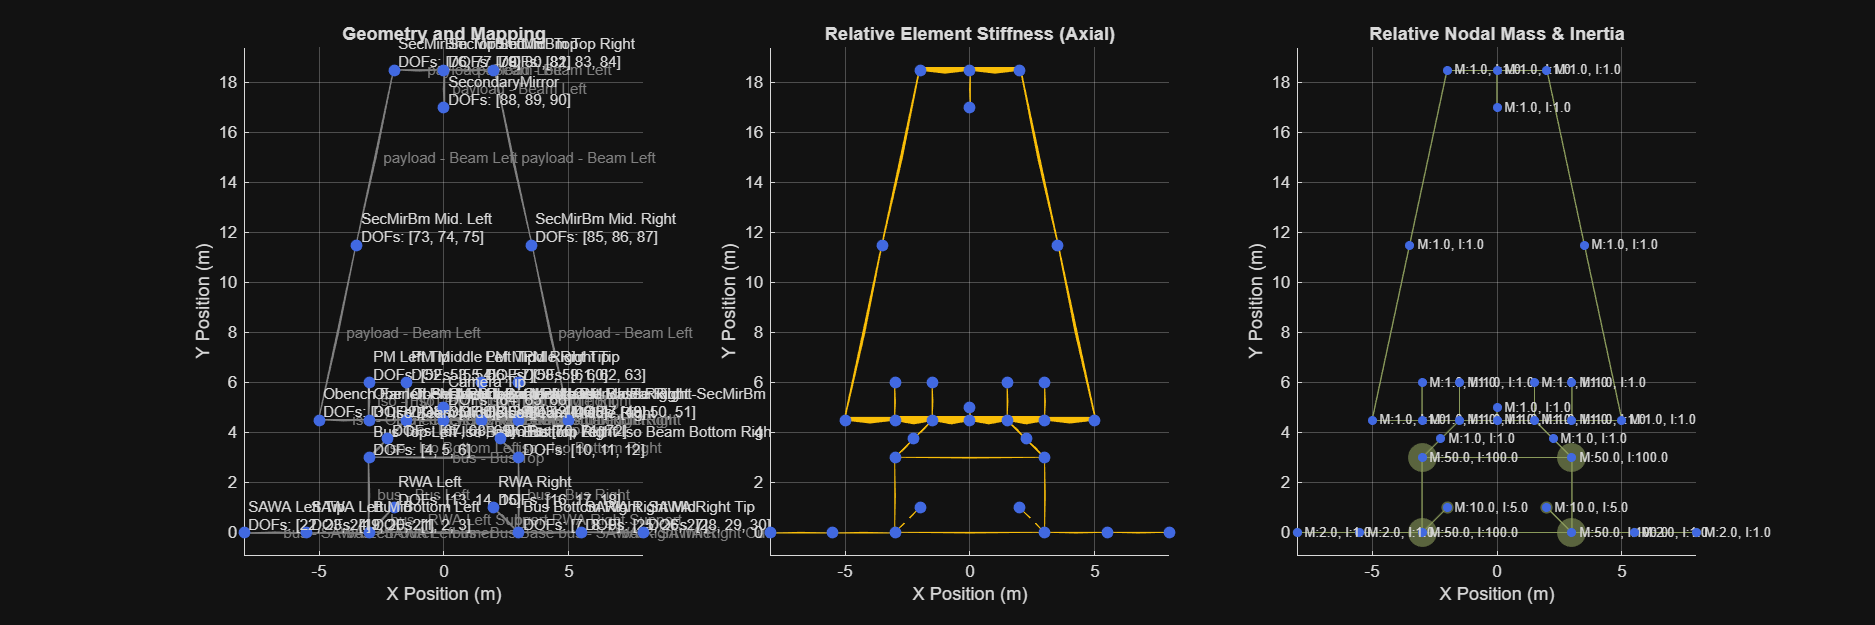

% Visualize the combined spacecraft FEM model
fem.plot_fem_model(SV);

Visualize the SV modes

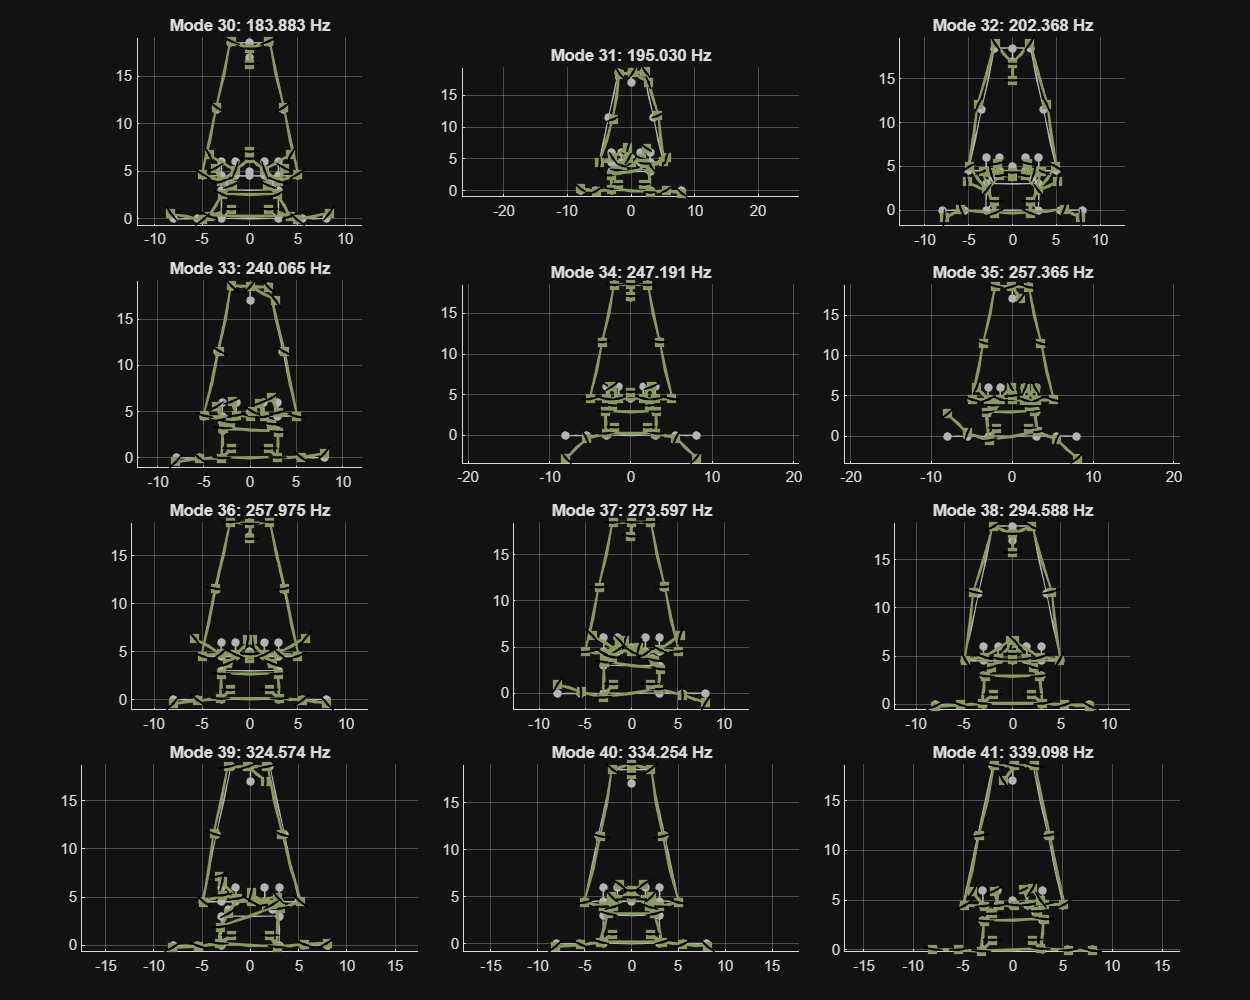

fem.plot_mode_shapes(SV,[SV.fn(30),SV.fn(41)])

Simulate disturbances from the RWAs

% Load options profile
% Compute the spacecraft response under reaction-wheel disturbances
% options_rwa_disturbances = options_rwa_disturbances();
% [X_rms_rwa_dist, X_rwa_dist] = fem.calculate_plot_rms(SV, options_rwa_disturbances);